## Define Experiment Parameters

%% Define where to look for rosbag files
project_root = "~/tagslam_ws/tagslam_root/src/continuum_mocap";
experiment_name = "helical_arm_1";

%% Parameterize tag locations
% ids of tags along the arm (and the order that we will store them in)
experiment_tags = [8 9 12 14 15 16 17]; % Tags 6 to 9 
base_tag_id = 9;

% the muscles that these muscles are attached to (in the same order) 
tag_muscle_ids = [1 1 4 4 4 3 3]; % List of muscle ids that the tags are attached to, in order

% Define t_tags: Percentage of tag position along total length of arm
% Tag in the middle of arm: t = 0.5
muscle_length_cm = 18 * 2.54;
muscle_spacing_cm = 13;
base_offset_cm = 0;
t_tags = ([1, 0, 3, 2, 1, 3, 2] * muscle_spacing_cm + base_offset_cm) / muscle_length_cm;

% Pressures corresponding to each experiment bag file in order
experiment_pressures = [0 10 20 30 40 50 60];
i_test_bag = 7;

## Retrieve Bag File

%% Find all bag files in bags dir corresponding to the desired experiment
%  that is specified by `experiment_name`
bags_dir = fullfile(project_root, "bags");

bag_files = dir(fullfile(bags_dir, experiment_name,'**/*.*'));  % Get list of files and folders in any subfolder
bag_files = bag_files(~[bag_files.isdir]);  % Remove folders from list

%% Search for localized(tagslammed) bags
% Create and fill selection mask
selection_mask = zeros(size(bag_files));
for i = 1 : length(bag_files)   
    if contains(bag_files(i).name, "localized")
        selection_mask(i) = 1;
    end
end
tagslam_bags = bag_files(logical(selection_mask)); % Apply selection mask

% Let's just test with the first bag file
bag = rosbag(fullfile(tagslam_bags(i_test_bag).folder, tagslam_bags(i_test_bag).name));

fprintf("Testing with bag: %s", tagslam_bags(i_test_bag).name)

Testing with bag: localized-60psi_2021-12-16-00-23-11.bag

## Create Arm Object

% Parameterize the arm
rho = 0.75 * 0.0254; % M, Radius
muscle_angle = deg2rad(12.5);

%% Construct pose matrices
% Transformations from world frame to each muscle

% Base muscle pose: pointing down, located at 0,0,0:
% The neutral pose is where the main contracting muscle will be. This is
% our "origin"
g_origin = SE3(eul2rotm([0, pi/2, 0], 'xyz'), [0 0 0]); % Frame corresponding to a muscle at the origin, pointing down

% Poses of muscle in world frame
% Muscles are arranged in equilateral triangle with radius rho
g_muscles = Arm3D.generate_g_muscles(rho, g_origin, 4, muscle_angle);
g_default_muscle = g_muscles{1}; % Default muscle: 
g_default_muscle(1:3, 4) = zeros(3, 1);

% Set position of first muscle to actually be at the origin
% We want to shift *everything* uniformly regardless of its pose, therefore
% it'll be a left-action:
% g_shift * g_1 = g_neutral
% Therefore g_shift = g_neutral * inv(g_1)
% Additionally, we rotate by a global 180deg so that all 3 muscles are
% aligned correctly
g_muscle_shift = g_default_muscle * inv(g_muscles{1});

% Then left-apply g_shift to all transformations
g_o = g_muscle_shift * g_origin;
g_muscles = cellfun(@(g_muscle) g_muscle_shift * g_muscle, g_muscles, 'uniformoutput', false);

% ===================
model_arm =  Arm3D(g_o, g_muscles, contraction_fit(0), 'plot_unstrained', false);
model_arm.n_spacers = 0;
fit_arm = copy(model_arm);

% Initialzie model arm:
psi = experiment_pressures(i_test_bag);
v_pressures = zeros(length(g_muscles), 1);
v_pressures(1) = psi;
v_l = contraction_fit(v_pressures);

h_o_model = model_arm.mat_N * v_l;

## Extract and Plot Transformations

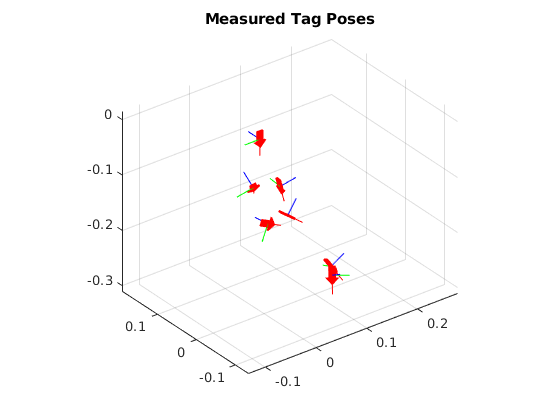

g_tags_meas = cell(size(experiment_tags));
for i = 1 : length(experiment_tags)
    id_tag = experiment_tags(i);
    
    % Make sure that the tag we're looking for has an existing
    % transformation in the TF tree
    if ~any(bag.AvailableFrames == sprintf("tag_%d", id_tag))
        error("Tag with id %d not found in list of available frames", id_tag)
    end
    
    tform_i = getTransform(bag, "lab", "tag_" + id_tag);
    R = quat2rotm(tform_i.Transform.Rotation.readQuaternion());
    % Apply extra 90 deg ccw rotation to correct for misplaced tags
    R = R * eul2rotm([pi/2, 0, 0], 'zyx');
    
    T_obj = tform_i.Transform.Translation;
    T = [T_obj.X; T_obj.Y; T_obj.Z];
    g_tags_meas{i} = SE3(R, T);
end

%% Plot measured tags
% First: I accidentally left the tags upside down - let's flip them around
g_tags_meas = cellfun(@(g_tag) g_tag * SE3(eul2rotm([0, 0, pi], 'xyz'), [0;0;0]), g_tags_meas, ...
    'UniformOutput', false);

% The default tag - the tag at the base of the default muscle - will
% actually be offset from the default muscle pose by a
% right-multiplication, corresponding to being offset in the tag-body Z
% direction.
g_tag_offset_right = SE3(eye(3), [0; 0; 0.4 * 0.0254]);
offsets = repelem({g_tag_offset_right}, length(experiment_tags));
g_default_muscle_upright = g_origin * SE3(eul2rotm([-pi/2, 0, 0], 'xyz'), [0, 0, 0]);
g_default_tag = g_default_muscle_upright * g_tag_offset_right;

% Transform all tag measurements so that the base muscle is at 0,0,0, and
% the base tag is offset by a right-transformation from that base muscle
% position. These offsets and poses are defined above.
g_base_tag = g_tags_meas{experiment_tags == base_tag_id};
g_tag_shift = g_default_tag * inv(g_base_tag);

% Apply the offset to each pose in the cell array
g_tags_meas = cellfun(@(g_tag) g_tag_shift * g_tag, g_tags_meas, ...
    'UniformOutput', false);

% Plot
fig = figure();
ax = axes(fig);
grid on
axis equal

plot_options = struct();
plot_options.framesize = 0.03;
plot_options.MeshFilePath = "tf_frame.stl";
[gh_tforms, T_tforms, quat_tforms] = plotTransformsSE_n(g_tags_meas, ax, plot_options);
title("Measured Tag Poses")

## Fit curve

% Fit curvature
warning('off', 'MATLAB:logm:nonPosRealEig') % Surpress matrix log warning
% TODO: Implement analytic SE3 logm?
[h_o_fit, g_tags_fit] = ...
    curve_fit_3d(model_arm, g_tags_meas, t_tags, tag_muscle_ids, ...
        init_val=h_o_model + [0;0;0;0;-0.2;0] , ... % Multiply by 1.5 so we don't just fit to the model solution
        offset=offsets);

## Initialize Plotting

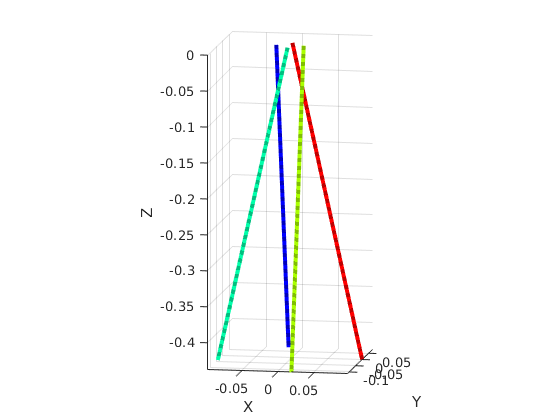

% Create figure
fig = figure();
ax = axes(fig);
grid on
axis equal

% Set plotting parameters
line_options_muscles = struct("LineWidth", 3);

f_arm_initialize_plotting = @(arm) arm.initialize_plotting(ax, line_options_muscles=line_options_muscles, resolution=40);

f_arm_initialize_plotting(model_arm);
f_arm_initialize_plotting(fit_arm);

% Darken plotting colors in model arm
for i = 1 : length(model_arm.muscles)
    color_current = model_arm.muscles(i).color;
    model_arm.muscles(i).color = hsv2rgb(rgb2hsv(color_current) .* [1, 1, 0.75]);
    model_arm.muscles(i).lh.LineStyle = ":";
end

% Bring solid line (Fitted muscle curves) to the back
for i = 1 : length(fit_arm.muscles)
    uistack(fit_arm.muscles(i).lh, "bottom");
end

arm_energy_from_h_o(h_o_model, v_l, fit_arm)

ans = 0.0049

[h_o_optim_numeric, U_optim] = fminsearch(@(h_o) arm_energy_from_h_o(h_o, v_l, fit_arm), h_o_model)

h_o_optim_numeric =     0.4136
   -0.0000
   -0.0034
    4.7988
    0.0000
    1.4350


U_optim = 0.0049

## Curve Fitting and Plotting

%h_o_model(4) = h_o_fit(4);
%h_o_fit(5) = 0;
model_arm.update_arm(v_l, h_o_optim_numeric)

ans =     0.4136
   -0.0000
   -0.0034
    4.7988
    0.0000
    1.4350


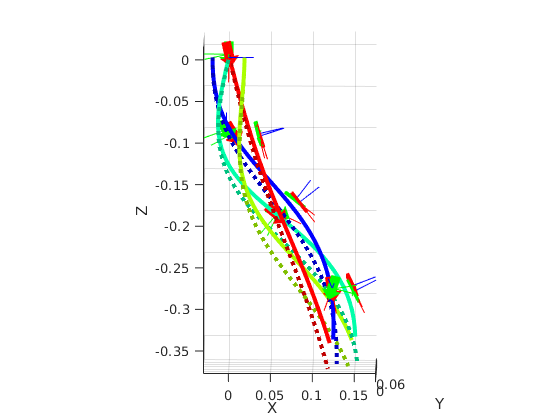

%model_arm.update_arm(v_l, h_o_model);
fit_arm.update_arm(v_l, h_o_fit);

plot_options.MeshColor = "green";
plotTransformsSE_n(g_tags_meas, ax, plot_options);
plot_options.MeshColor = "red";
plotTransformsSE_n(g_tags_fit, ax, plot_options);

plotTransforms(model_arm.g_o(1:3, 4)', rotm2quat(model_arm.g_o(1:3, 1:3)), parent=ax, framesize=plot_options.framesize);

view([0.683 7.896])

mat_h_tilde_model = [model_arm.muscles.h_tilde]

mat_h_tilde_model =     0.3962    0.4236    0.4510    0.4236
   -0.0023    0.0003    0.0029    0.0003
   -0.0000   -0.0034    0.0000    0.0034
    4.9956    4.6850    4.3744    4.6850
   -0.3623    1.0386    2.4396    1.0386
    0.0000    1.4350   -0.0000   -1.4350


mat_h_tilde_fit = [fit_arm.muscles.h_tilde]

mat_h_tilde_fit =     0.3681    0.4013    0.4313    0.3981
   -0.0134   -0.0084   -0.0042   -0.0091
   -0.0000   -0.0024    0.0000    0.0024
    5.2332    4.8528    4.5095    4.8899
   -0.5523    1.1636    2.7122    0.9963
    0.0857    1.6719   -0.0857   -1.6719


for i = 1
    [U_model_total, U_model_indiv] = calculate_energy(mat_h_tilde_model, v_l)
    [U_model_total_normalized, U_model_indiv_normalized] = calculate_energy(mat_h_tilde_model, v_l, true)
    
    [U_fit_total, U_fit_indiv] = calculate_energy(mat_h_tilde_fit, v_l)
    [U_fit_total_normalized, U_fit_indiv_normalized] = calculate_energy(mat_h_tilde_fit, v_l, true)
end

U_model_total = 0.0049

U_model_indiv =     0.0021    0.0010    0.0008    0.0010


U_model_total_normalized = 0.0121

U_model_indiv_normalized =     0.0023    0.0030    0.0037    0.0030


U_fit_total = 0.0089

U_fit_indiv =     0.0012    0.0031    0.0013    0.0034


U_fit_total_normalized = 0.0285

U_fit_indiv_normalized =     0.0071    0.0077    0.0055    0.0082


function [U_total, U_individual] = calculate_energy(h_tilde, v_l, normalize, mat_K)
    arguments
        h_tilde (6, :)
        v_l
        normalize = false;
        %mat_K = diag([1, 5, 5, 0, 6.7500e-05, 6.7500e-05]);
        mat_K = diag([1, 5, 5, 0, 0.00012, 0.00012]);
    end
    
    if normalize
        % Normalize shearing and curvature
        h_tilde(2:end, :) = h_tilde(2:end, :) ./ h_tilde(1, :);
    end
    
    %h_tilde(1, :) = (h_tilde(1, :) ./ v_l(:)') - 1;
    h_tilde (1, :) = h_tilde(1, :) - v_l(:)';
    
    mat_U = eye(size(h_tilde, 2)) .* (h_tilde' * mat_K * h_tilde);
    
    U_individual = sum(mat_U);
    U_total = sum(U_individual);
end

function U_total = arm_energy_from_h_o(h_o, v_l, arm_obj)
    mat_h_tilde = zeros(6, length(arm_obj.muscles));
    for i = 1 : length(arm_obj.muscles)
        mat_h_tilde(:, i) = arm_obj.muscles(i).adjoint_X_o * h_o;
    end
    
    U_total = calculate_energy(mat_h_tilde, v_l, false);
end